# EXAM 2 - COMPUTATION:

# Amelia Rotondo - CWID: 887925113

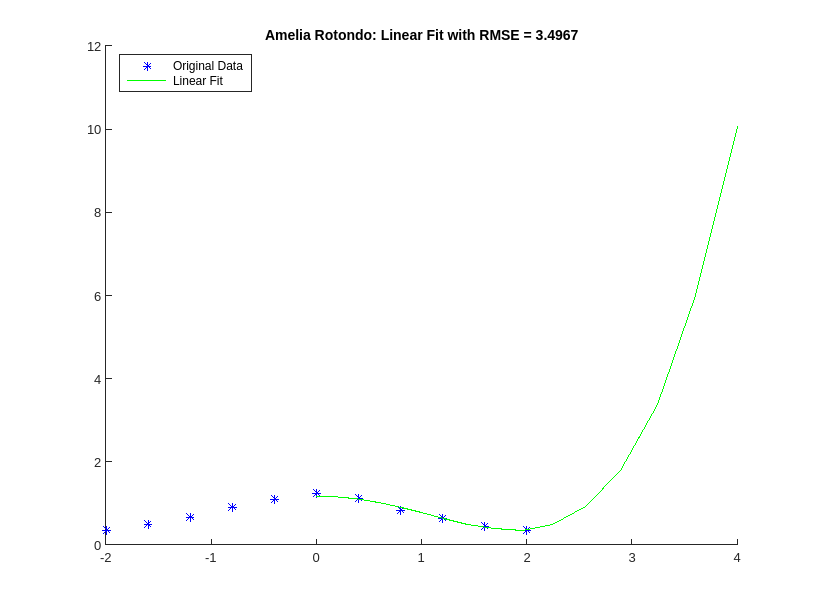

% Initialize Data
x = -2:0.4:2;
y1 = [0.35 0.481 0.651 0.906 1.084];
y2 = [1.242 1.119 0.833 0.643 0.448 0.357];
y = [y1 y2];
xx = min(x):0.1:max(x);

% produce a Linear Fit
%{
I KNOW MY GRAPH IS WRONG 
BUT YOU CAN SEE THAT I ALMOST HAD IT 
IF ONLY I DIDNT WASTE TIME 
DOING MATH BY HAND IN THE FIRST HALF OF THE TEST
%}
X = x.^2;
XX = xx .^2;
Y = 1./y;
P = polyfit(X, Y, 1);
C = p(1);
D = 1 /p(2);
YY = polyval(p, XX);

% Find Root-Mean Square Error
fit_rmse = myRmse(y,YY);

% Plot Your Results
titlename = append('Amelia Rotondo: Linear Fit with RMSE = ', num2str(fit_rmse));
figure(1); clf; hold on;
plot(x, y, 'b*', 'DisplayName', 'Original Data');
plot(XX, YY, 'g', 'DisplayName', 'Linear Fit');
hold off;
title(titlename);
legend('Location', 'best');

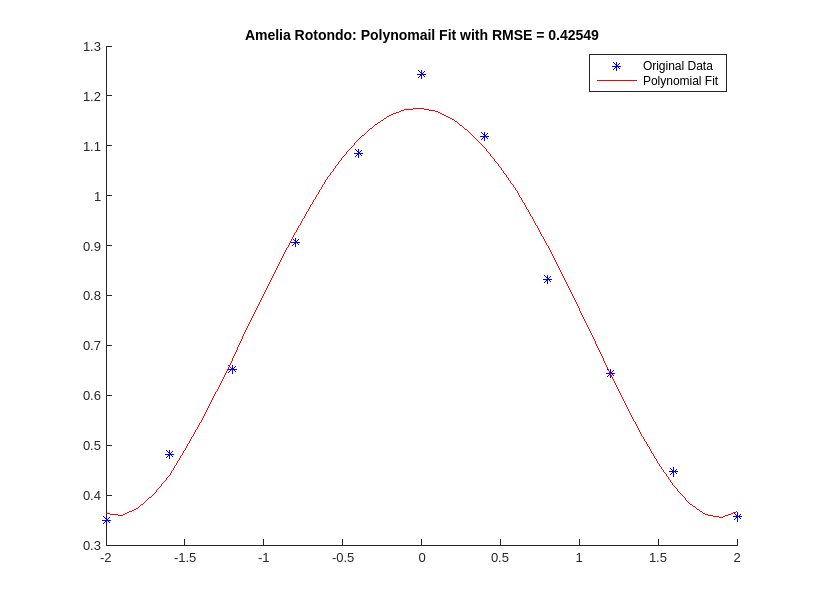


% produce a Polynomial of Degree 4
p = polyfit(x, y, 4);
yy4 = polyval(p, xx); 

% Find Root-Mean Square Error
poly_rmse = myRmse(y,yy4);

% Plot Your Results
titlename = append('Amelia Rotondo: Polynomail Fit with RMSE = ', num2str(poly_rmse));
figure(2); clf; hold on;
plot(x, y, 'b*', 'DisplayName', 'Original Data');
plot(xx, yy4, 'r', 'DisplayName', 'Polynomial Fit');
hold off;
title(titlename);
legend('Location', 'best');

## Function for the Root-Mean Squared Error:

function [rmse] = myRmse(ypoints, yfunc)
    mse = myMse(ypoints, yfunc);
    rmse = sqrt(mse);
end

% Mean Squared Error Function
function [mse] = myMse(ypoints, yfunc)
SSE = 0; 
for i = 1:length(ypoints)
    SSE = SSE + (ypoints(i)-yfunc(i))^2;
end
mse = (1/length(ypoints))*SSE;
end
